sourceImg = imread('im9933.jpg');
gray = rgb2gray(sourceImg)

gray = 333×500 uint8 矩阵
    19    18    19    19    17    17    19    19    19    19    20    20    20    20    20    19    18    19    21    20    20    19    17    20    18    20    20    19    19    19    19    20    20    20    21    22    25    30    33    39    40    45    49    52    56    61    66    71    74    78
    18    18    19    19    18    18    19    19    16    17    18    18    19    19    19    19    20    21    20    16    18    22    20    18    19    20    19    18    18    19    21    23    26    28    32    35    40    44    47    52    58    62    66    69    73    78    83    87    93    96
    19    18    18    19    18    19    20    19    19    19    20    20    20    20    19    19    18    19    20    19    20    20    19    21    20    22    22    22    24    28    31    34    37    40    46    50    55    60    63    68    73    77    80    84    89    94    98   102   106   109
    20    19    19    19    19    19    20    19    19    19    20    20 

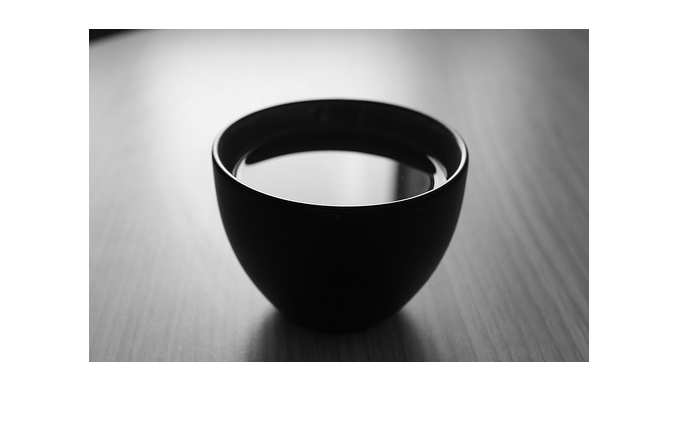

imshow(sourceImg)

[rows, cols] = size(gray)

rows = 333

cols = 500

disp('source_success')

source_success


arcpoints = load ('ske\im9933arcpoints.txt','-ascii');
[arcpointsizex,~] = size(arcpoints);
arc = 0;
new_label = 0;

cellArc = {};
for i = 1 : arcpointsizex
    arc_label = arcpoints(i,1);
    if arc~=arc_label
        if arc > 0
            cellArc{new_label} = H;
        end
        arc = arc_label;
        new_label = new_label+1;

        H = [];
        k = 1;
    end
    H(k,1) = arcpoints(i,2)+1;
    H(k,2) = arcpoints(i,3)+1;
    H(k,3) = arcpoints(i,1);
    k = k + 1;
end
disp('success_1')

success_1


% Successfully saved arcs to cellArc
% coordinate +1, +1

[~, arc_num] = size(cellArc);
thinArc = cell(arc_num,1);
sol = zeros(5,arc_num);
for i = 1 : arc_num
    [point_num,~] = size(cellArc{i});
    img = full(sparse(cellArc{i}(:,1),cellArc{i}(:,2),ones(point_num,1)));
    [thinArc{i}(:,1),thinArc{i}(:,2), ~ ] = find(bwskel(logical(img)));
    [thin_num,~] = size(thinArc{i});
    F = zeros(point_num,5);
    G = zeros(point_num,1);
    for j = 1 : thin_num
        F(j,1) = thinArc{i}(j,1)^2 / rows^2;
        F(j,2) = thinArc{i}(j,1) * thinArc{i}(j,2) / (cols * rows);
        F(j,3) = thinArc{i}(j,2)^2 / (cols ^ 2);
        F(j,4) = thinArc{i}(j,1) / (rows);
        F(j,5) = thinArc{i}(j,2) / cols;
        G(j) = 1; % 可优化
    end
    sol(:,i) = F\G;
end

disp('success_2')

success_2


% thin Arc Done
% sol done
% F,G is transformed 1/sizex, 1/sizey

## cocluster

### read from sol

load("/home/wu/codes/ELSDc/out_ellipse.txt");
% tmp = out_ellipse(:,6:12);
% output = [out_ellipse(:,6:10),abs(out_ellipse(:,12)-out_ellipse(:,11))];
output = out_ellipse(:,6:10)';

### calculate

### old

    1.0068



     2



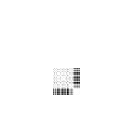

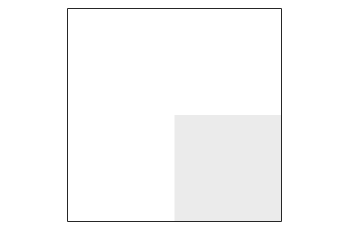

    0.4507



     3



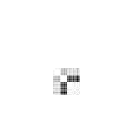

    0.2870



     4



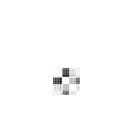

    0.2576



     5



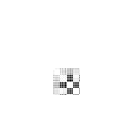

    0.2321



     6



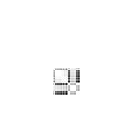

    0.0879



     7



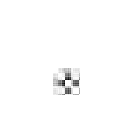

    0.1227



     8



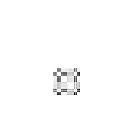

    0.1070



     9



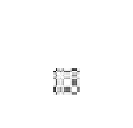

    0.0703



    10



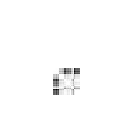

    0.0439



    11



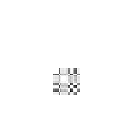

    0.0484



    12



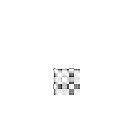

    0.0304



    13



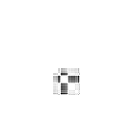

    0.0222



    14



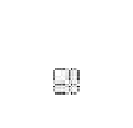

    0.0204



    15



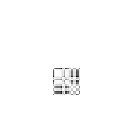

    0.0191



    16



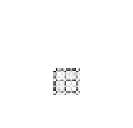

    0.0149



    17



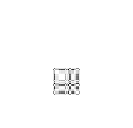

    0.0149



    18



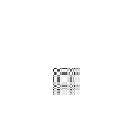

    0.0077



    19



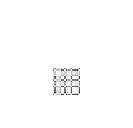

    0.0029



    20



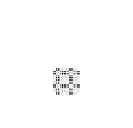

    0.0052



    21



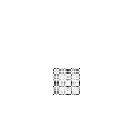

    0.0019



    22



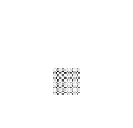

    0.0012



    23



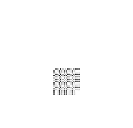

   7.5637e-04



    24



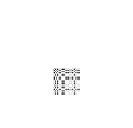

   2.1713e-04



    25



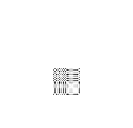

% output = sol(:,sol(1,:).^2-4.*sol(2,:)<0);
% output = sol;
% change output to sol
[~,out_num] = size(output);
cor = zeros(out_num);
for i = 1 : out_num
    for j = 1 : out_num
        cor(i,j) = Correlation(output(:,i),output(:,j));
    end
end
[u,s,~]=svd(cor);
Sam = u*s^(1/2);
% Sam = cor*u(:,1:5);
sums = NaN(1,50);
C = cell(10,1);
id = cell(10,1);
output = output';
for j = 2:25 % kmeans 的 k
    [ind,M,sumd] = kmeans(Sam,j);
    [~,I]=sort(ind);
    newcor = cor(I,I);
    img=mat2gray(newcor);%将数值矩阵X转换为灰度图像
    C(j)={M};
    id(j)={ind};
    sums(j) = sum(sumd);
    disp(sums(j))
    disp(j)
    figure,imshow(img);
    tmp = zeros(j,5);
    cnt = zeros(j);
    for i = 1:size(output,1)
        tmp(ind(i),:) = tmp(ind(i),:)+output(i,:);
        cnt(ind(i)) = cnt(ind(i)) + 1;
    end
    for i = 1:j
        tmp(i,:) = tmp(i,:)/cnt(i);
    end

    drawEllipses(tmp',"666.jpg")
end

plot(sums) % 误差图 k = 4

j = 12;
[ind,M,sumd] = kmeans(Sam,j);
[~,I]=sort(ind);
newcor = cor(I,I);
img=mat2gray(newcor);%将数值矩阵X转换为灰度图像
C(j)={M};
id(j)={ind};
sums(j) = sum(sumd);
disp(sums(j))

    0.0338



disp(j)

    12



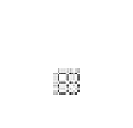

figure,imshow(img);

k=j;

output = output';

## find result and draw

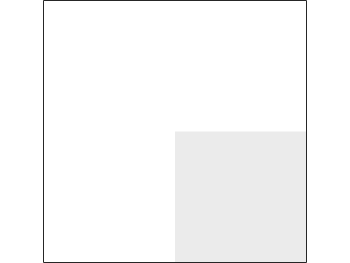


tmp = zeros(j,5);
cnt = zeros(j);
for i = 1:size(output,1)
    tmp(ind(i),:) = tmp(ind(i),:)+output(i,:);
    cnt(ind(i)) = cnt(ind(i)) + 1;
end
for i = 1:j
    tmp(i,:) = tmp(i,:)/cnt(i);
end

drawEllipses(tmp',"666.jpg")

## old version


group = id{k};
cocl = zeros(out_num,k);
for i = 1 : k
    [y,z] = find(group == i);
    f = full(sparse(y,z,1));
    [x,~] = size(f);
    cocl(1:x,i) = f;
end
conum = zeros(1,k);
for i = 1 : k
    conum(i) = sum(cocl(:,i));
end
disp('success_3')

success_3


% construct group matrix
% k columns in matrix cocl, each column tells us which arc belongs to
% which ellipse

output * cocl

ans =  -208.5049  -50.6982
   51.7912  223.5183
  -46.1307 -480.2376
  103.7420  -18.5732
    1.1928  166.6706


cocl

cocl =      1     0
     1     0
     1     0
     1     0
     1     0
     0     1
     0     1
     0     1
     0     1
     0     1


conum

conum =     16    26


s = [];
for i = 1 : arc_num
    s = [s;thinArc{i}];
end
S = sparse(s(:,1),s(:,2),1);
imshow(full(S))
% gather all thin arc points

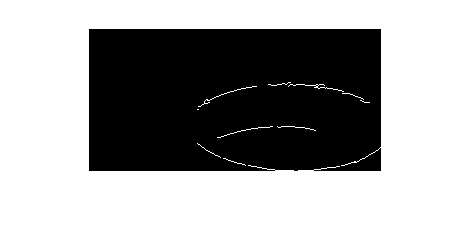

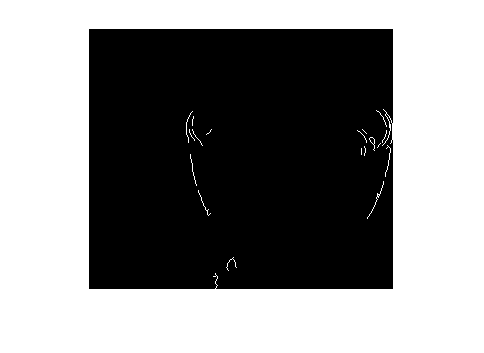

% draw cocl (sel) (sel for select)
% sel = 5;

% mkdir('im9933')
for sel = 1 : k
    s = [];
    for i = 1 : out_num
        if cocl(i,sel)>0
            s = [s;thinArc{i}];
        end
    end
    S = sparse(s(:,1),s(:,2),1);
    figure,imshow(full(S))
end